Load Data

load Testdata_Capsensor_Horizontal.mat
load Testdata_Coil_Horizontal.mat
sampling_rate = 20.9; 

3.Horizontal Smooth +5

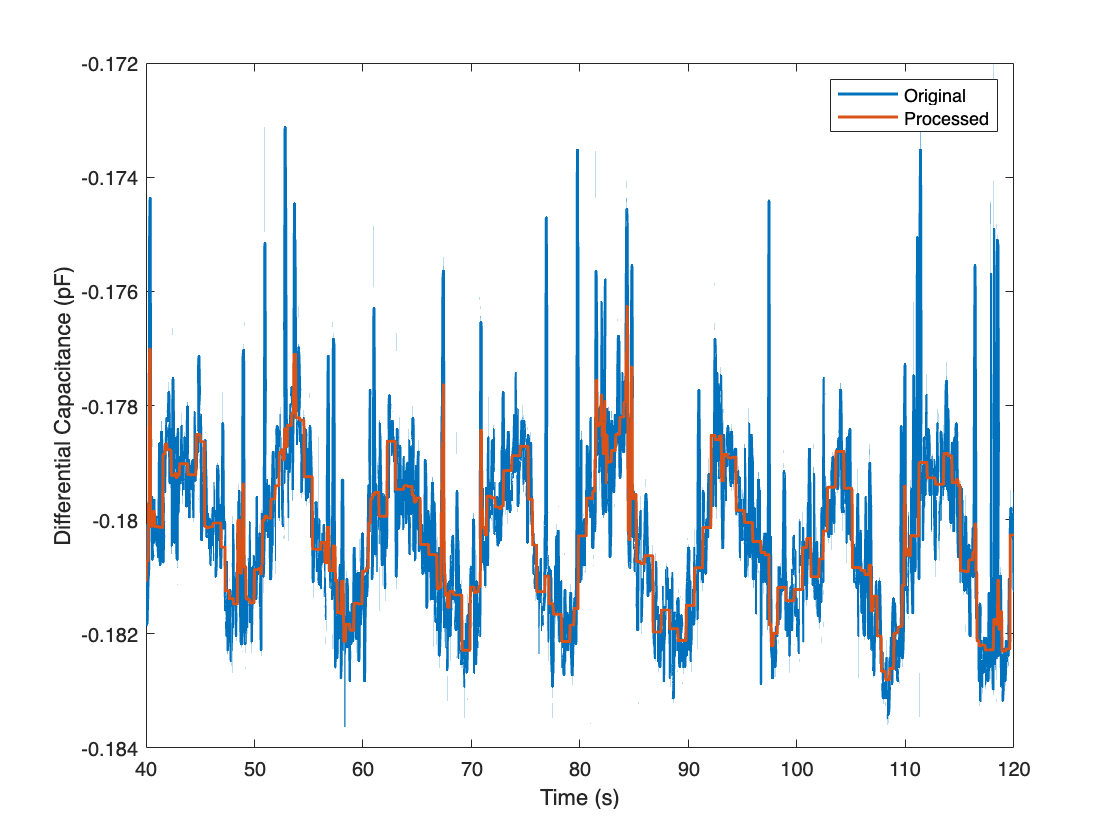

clf

capDataMain = capDataSmoothPursuit;
mainCoil = smoothPursuit;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/sampling_rate;

plot(capTime,capDataMain,LineWidth=1.5)
hold on


WL_DEN_LVL = 4; % n < log2_sampleAmount
WL_TYPE = 'bior1.5';
% Outlier removal optional
capDataMain = filloutliers(capDataMain,'linear','movmedian',10);

plot(capTime,wlcomp(capDataMain,WL_TYPE,WL_DEN_LVL,0),LineWidth=1.5)

xlim([40 120])
hold off
ylabel("Differential Capacitance (pF)")
xlabel("Time (s)")
legend("Original","Processed")

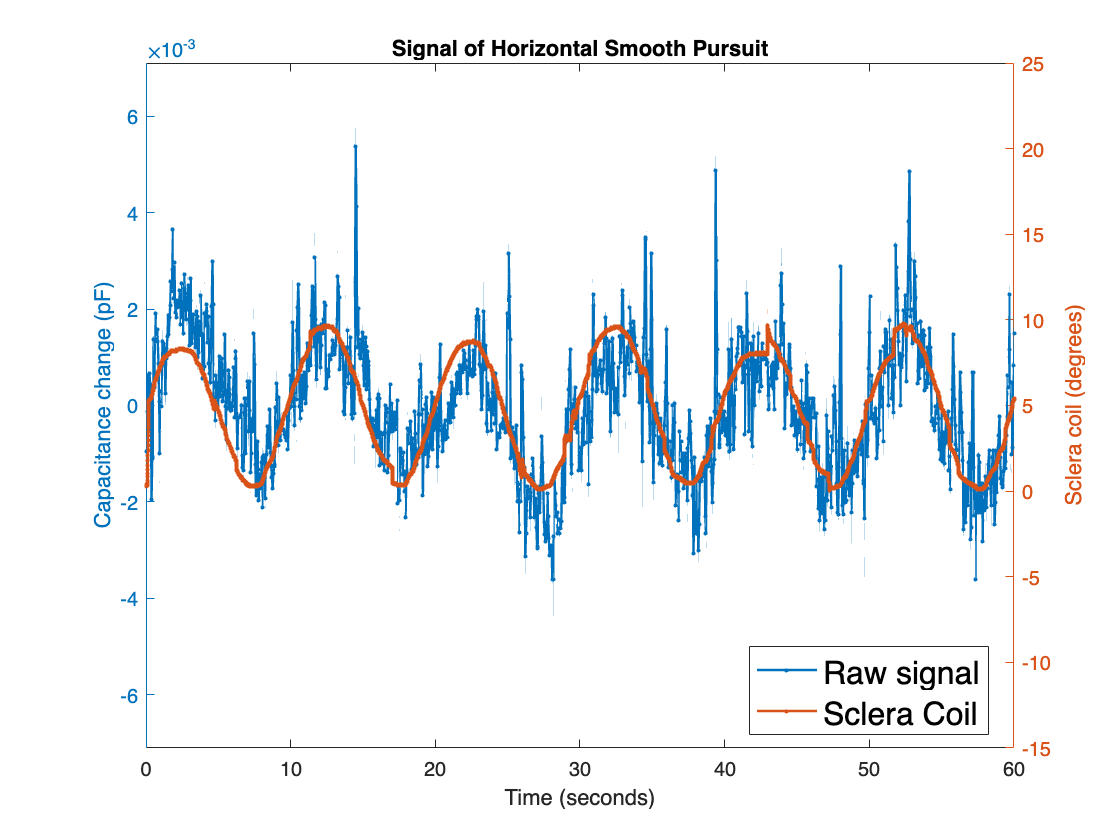

capDataPreproc = detrend(capDataMain,1);
capDataPreproc = circshift(capDataPreproc,-20); 
capDataProcessed = capDataPreproc;


clf

yyaxis left
plot(capTime,capDataProcessed,'.-',LineWidth=1.2)
ylim([-7.1e-3 7.1e-3])
hold on
ylabel("Capacitance change (pF)")
yyaxis right
plot(coilTime,mainCoil,'.-',LineWidth=1.2)
ylabel("Sclera coil (degrees)")
xlabel("Time (seconds)")
ylim([-15 25])
xlim([0 60])
title("Signal of Horizontal Smooth Pursuit")
legend("Raw signal","Sclera Coil",Location="best",FontSize=16)

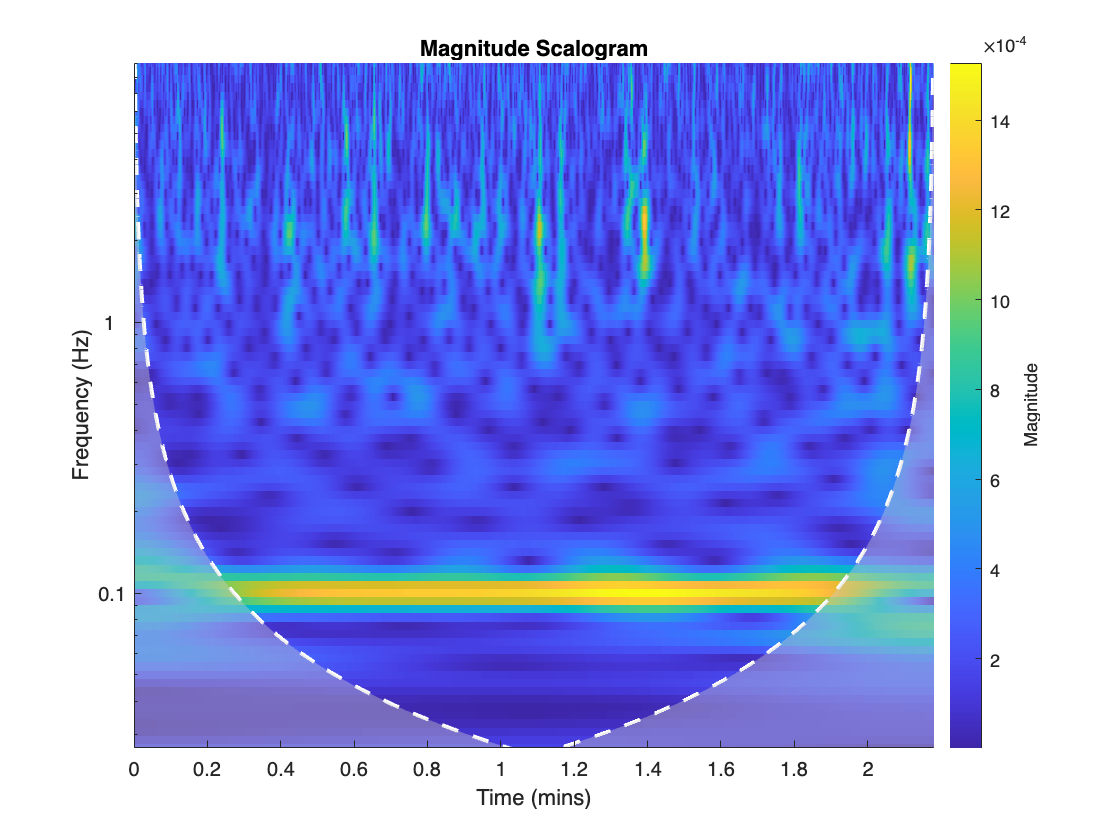

cwt(capDataPreproc,sampling_rate)

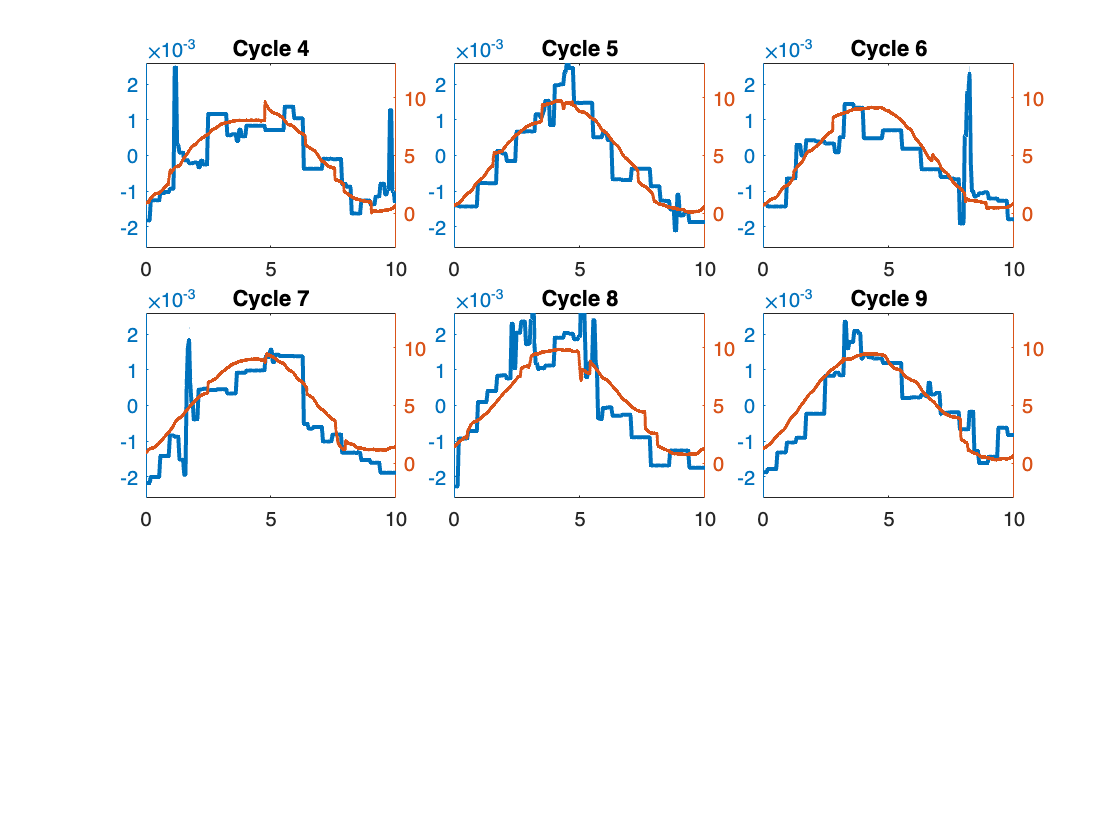

PERIOD_TIME  = 10;
WL_THR_MTD = 'Bayes'; 
WL_TYPE = 'bior1.5';
WL_DEN_LVL = 4; 
START_TIME = 8.2;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;

corra = zeros(1,9);
clear outarr

locs = floor(START_TIME*sampling_rate+1):floor(PERIOD_TIME*sampling_rate):length(capDataLocal);
coilLocs = 1000*START_TIME+1:floor(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 10]) % Maximum allowed = 10 segments

    outarr{peaknum,1} = wlcomp(capDataPreproc(locs(peaknum):locs(peaknum+1)),WL_TYPE,WL_DEN_LVL,0);
    outarr{peaknum,2} = capDataPreproc(locs(peaknum):locs(peaknum+1));

end
clear capvar coilvar
coilvar = [];
capvar = [];

clf
tiledlayout(3,3,'TileSpacing','tight')
for ix = 4:9 % 6 * 10
    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000 + 1.2);

        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on

        ylim([-2.6e-3 2.6e-3])


        yyaxis right
        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on
        ylim([-3 13])
        hold off
        xlim([0 10])
        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1})); % RAW
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

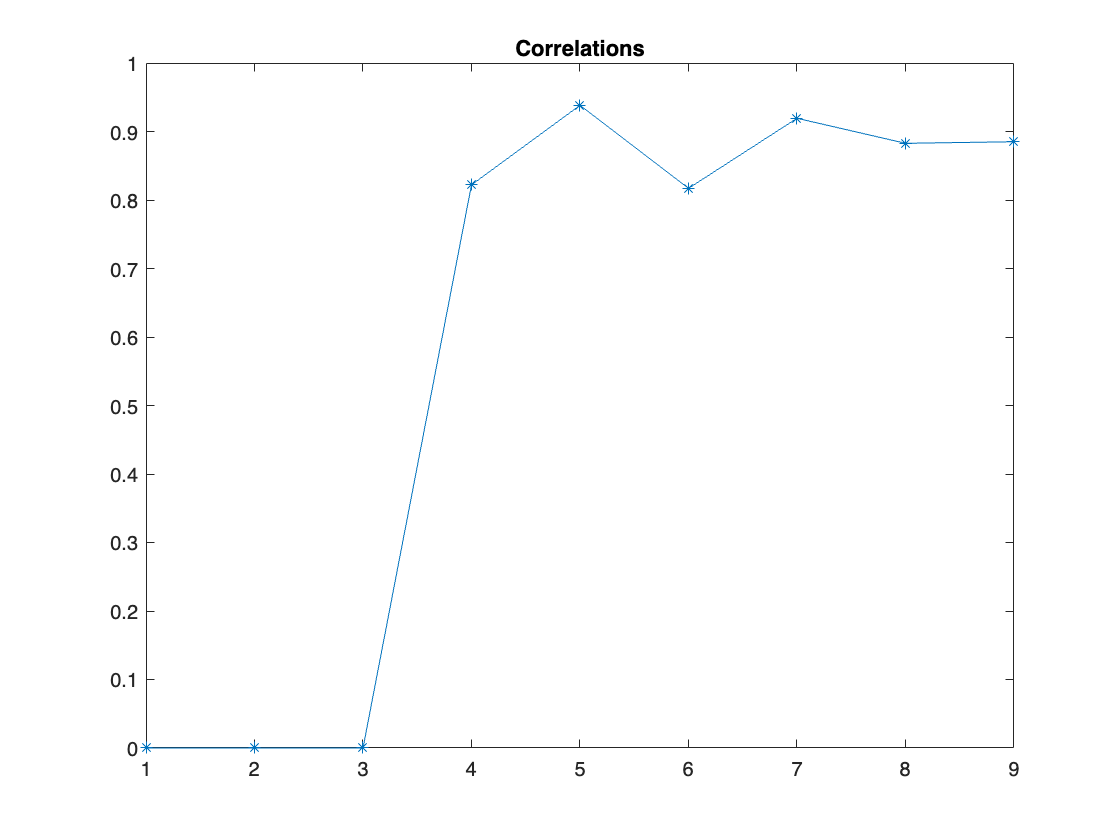

clf
plot(corra,"*-")
title("Correlations")

max(corra(corra ~= 0))

ans = 0.9383

mean(corra(corra ~= 0))

ans = 0.8774

std(corra(corra ~= 0))

ans = 0.0495

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

6.Horizontal Saccade +5

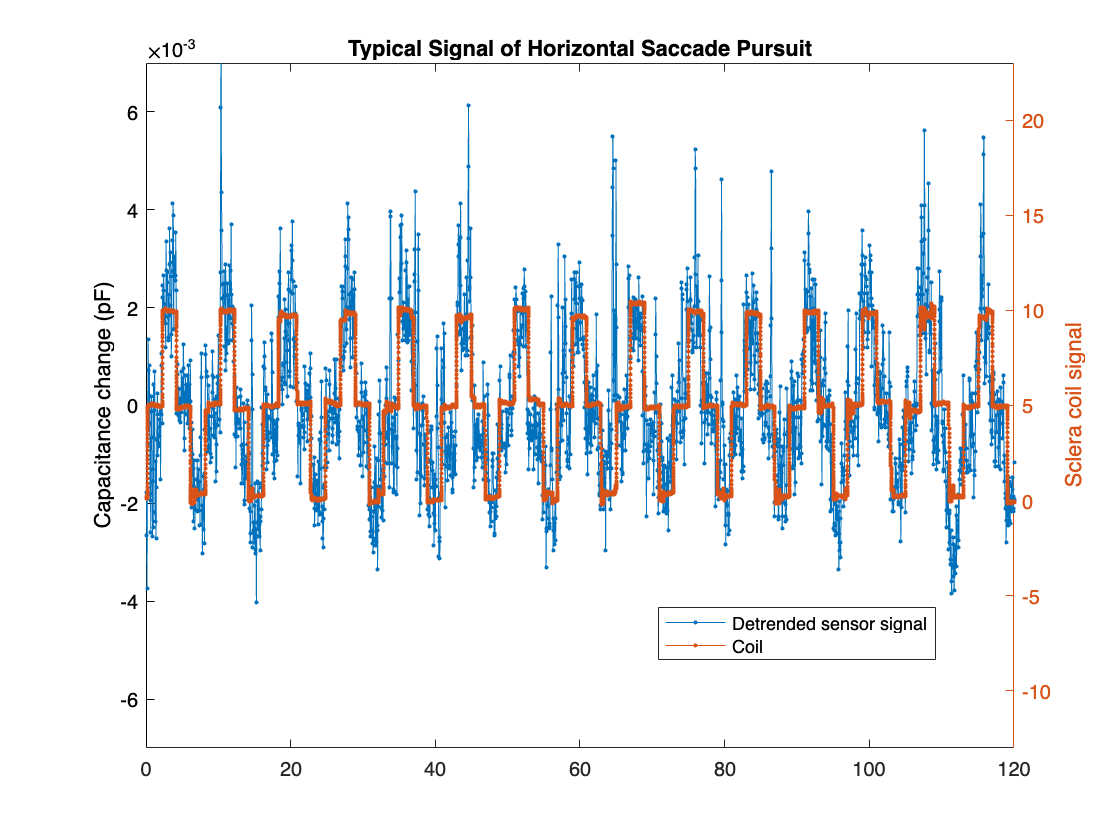

clf
capDataMain = capDataSaccadeTracking;

csmall = find(capDataMain==min(capDataMain));
capDataMain(csmall) = [];

capDataMain = filloutliers(capDataMain,'linear','movmedian',10);

mainCoil = saccadeTracking;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/sampling_rate;


capDataPreproc = detrend(capDataMain,2);
capDataPreproc = circshift(capDataPreproc,-10);

capDataProcessed = capDataPreproc;


yyaxis left
plot(capTime,capDataProcessed,'.-')
ylim([-7e-3 7e-3])
ylabel("Capacitance change (pF)")
hold on
yyaxis right
plot(coilTime,mainCoil,'.-')
ylabel("Sclera coil signal")
ylim([-13 23])
xlim([0 120])
hold off
legend("Detrended sensor signal","Coil",Location="best")
title("Typical Signal of Horizontal Saccade Pursuit")

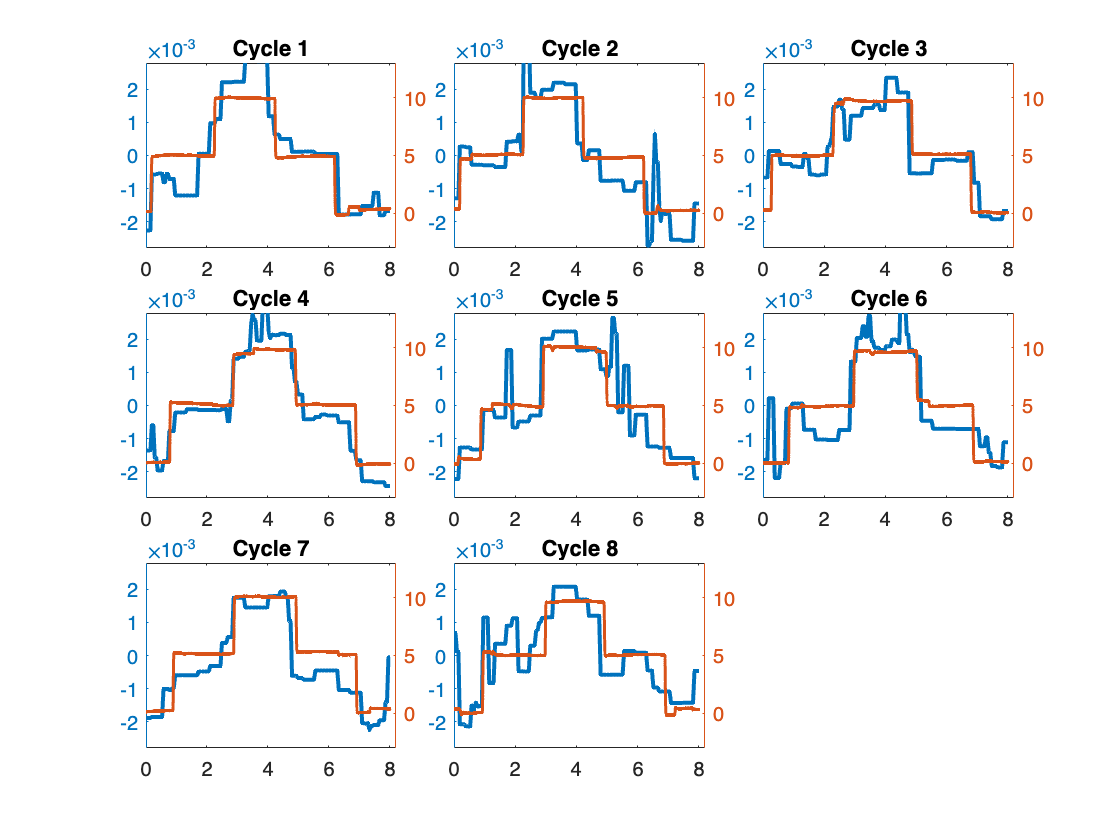

PERIOD_TIME  = 8;
WL_DEN_LVL = 4; 
WL_THR_MTD = 'Bayes'; 
WL_TYPE = 'bior1.5';
PEAK_PROM_CAP = .5e-3;
PEAK_PROM_COIL = 0.2;

START_TIME = 0;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;

corra = zeros(1,9);
clear outarr


locs = floor(START_TIME*sampling_rate+1):floor(PERIOD_TIME*sampling_rate):length(capDataLocal);
coilLocs = 1000*START_TIME+1:floor(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 10]) % Maximum allowed = 10 segments

    outarr{peaknum,1} = wlcomp(capDataPreproc(locs(peaknum):locs(peaknum+1)),WL_TYPE,WL_DEN_LVL,0);

    outarr{peaknum,2} = capDataPreproc(locs(peaknum):locs(peaknum+1));

end
clear capvar coilvar
coilvar = [];
capvar = [];
clf
tiledlayout(3,3,'TileSpacing','tight')
for ix = 1:8 % 8*8 > 60
    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000 + 1.2);
        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on
        ylim([-2.8e-3 2.8e-3])

        yyaxis right
        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on
        ylim([-3 13])
        hold off
        xlim([0 8.2])
        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1})); % RAW
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

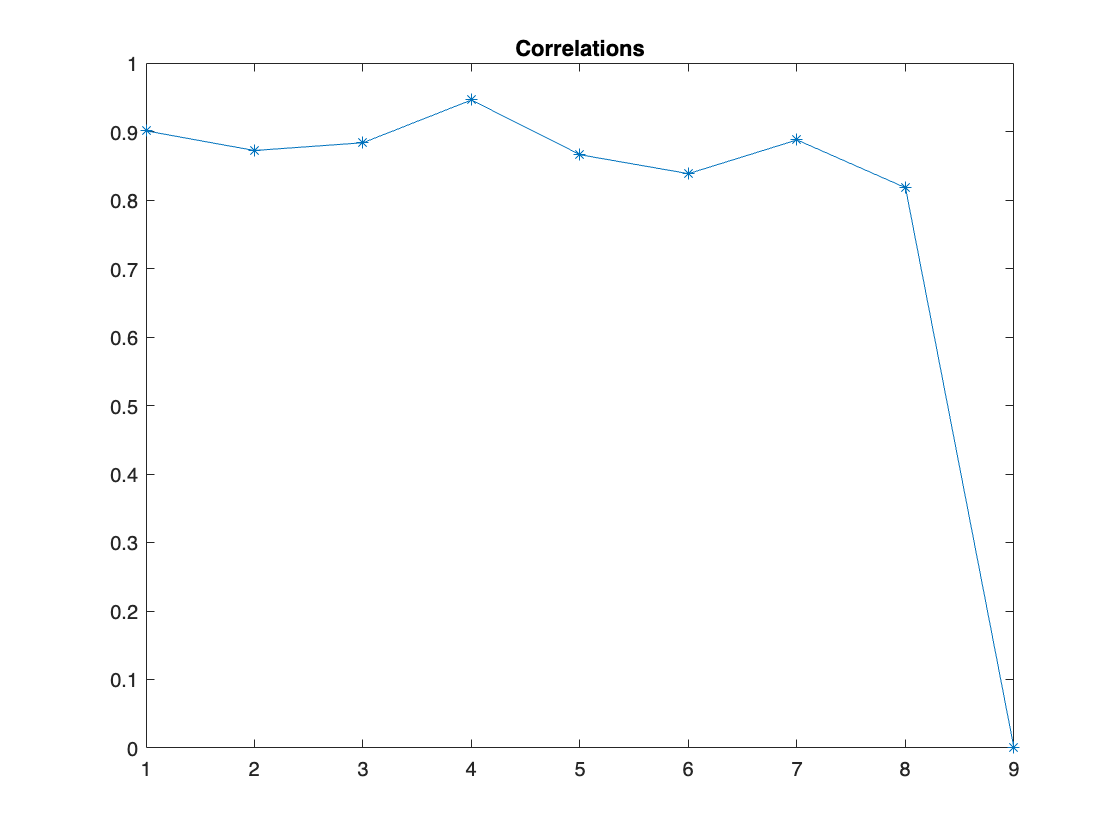

clf
plot(corra,"*-")
title("Correlations")

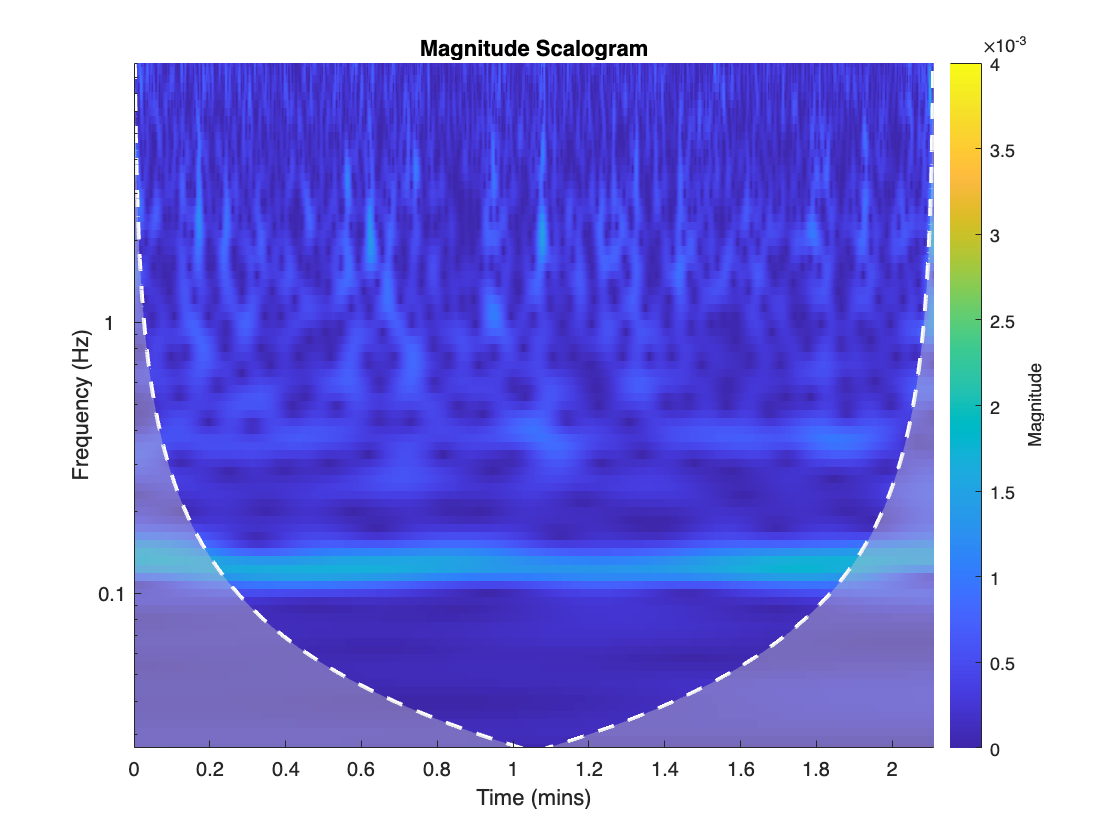

cwt(capDataPreproc,sampling_rate)
caxis([0 4e-3])

max(corra(corra ~= 0))

ans = 0.9460

mean(corra(corra ~= 0))

ans = 0.8766

std(corra(corra ~= 0))

ans = 0.0389

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

1.Horizontal Static Measurement

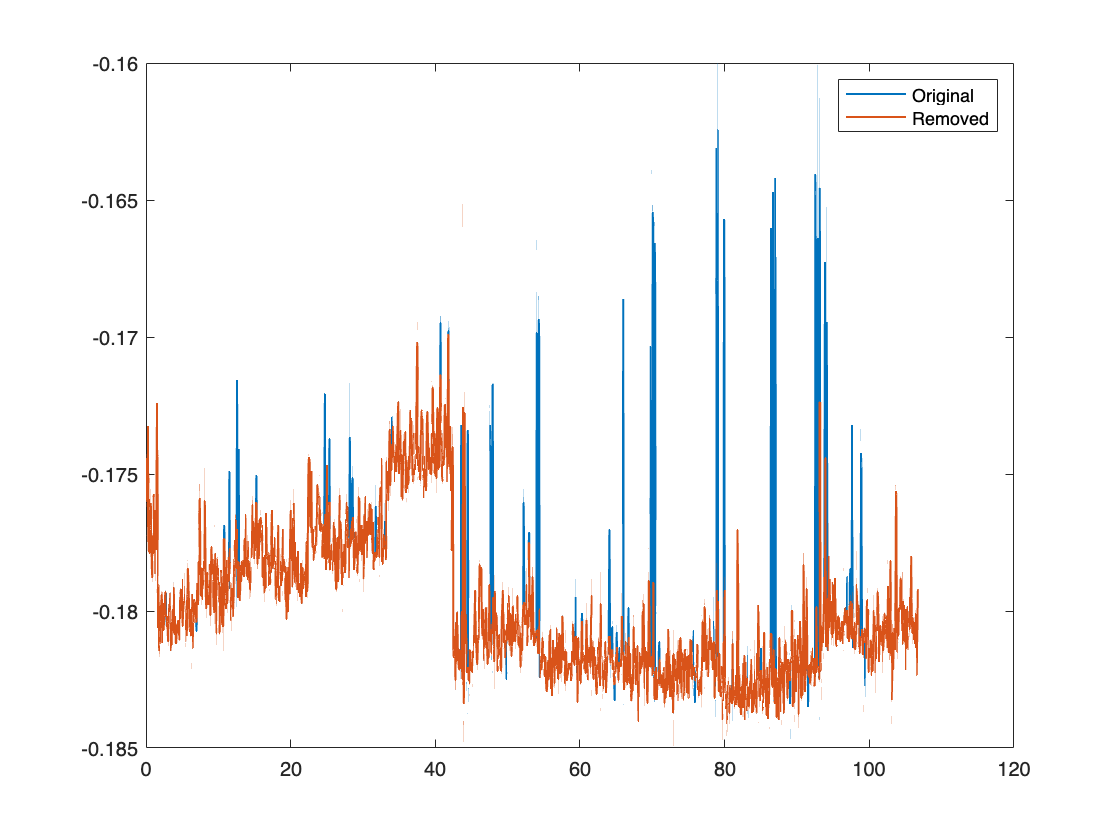

clf
capDataMain = capDataFixationTracking;

mainCoil = fixationTracking;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/sampling_rate;

plot(capTime,capDataMain,LineWidth=1)
hold on

capDataMain = filloutliers(capDataMain,'previous','movmedian',10);

plot(capTime,capDataMain,LineWidth=1)
hold off
legend("Original","Removed")

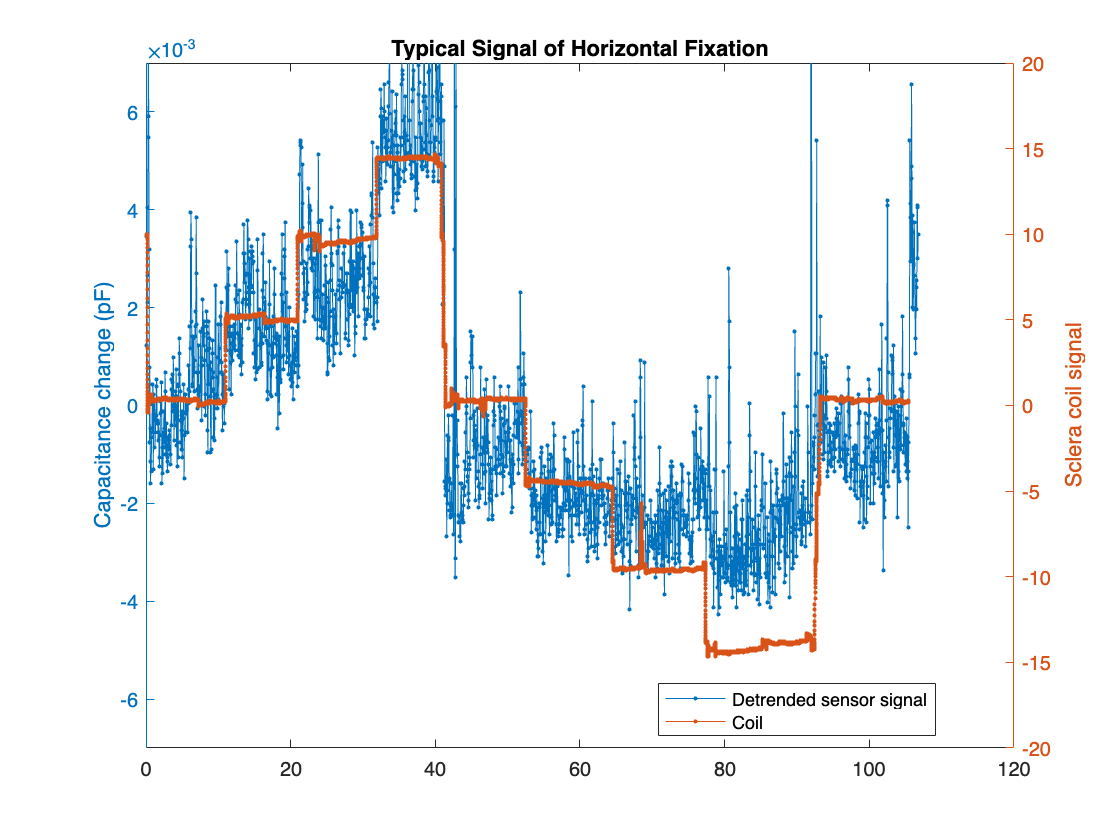

%= Data Preprocessing
capDataPreproc = detrend(capDataMain,0);
capDataPreproc = circshift(capDataPreproc,-25);

capDataProcessed = capDataPreproc;


clf

yyaxis left
plot(capTime,capDataProcessed,'.-')
ylim([-7e-3 7e-3])
ylabel("Capacitance change (pF)")
hold on
yyaxis right
plot(coilTime,mainCoil,'.-')
ylabel("Sclera coil signal")
ylim([-20 20])
hold off
legend("Detrended sensor signal","Coil",Location="best")
title("Typical Signal of Horizontal Fixation")

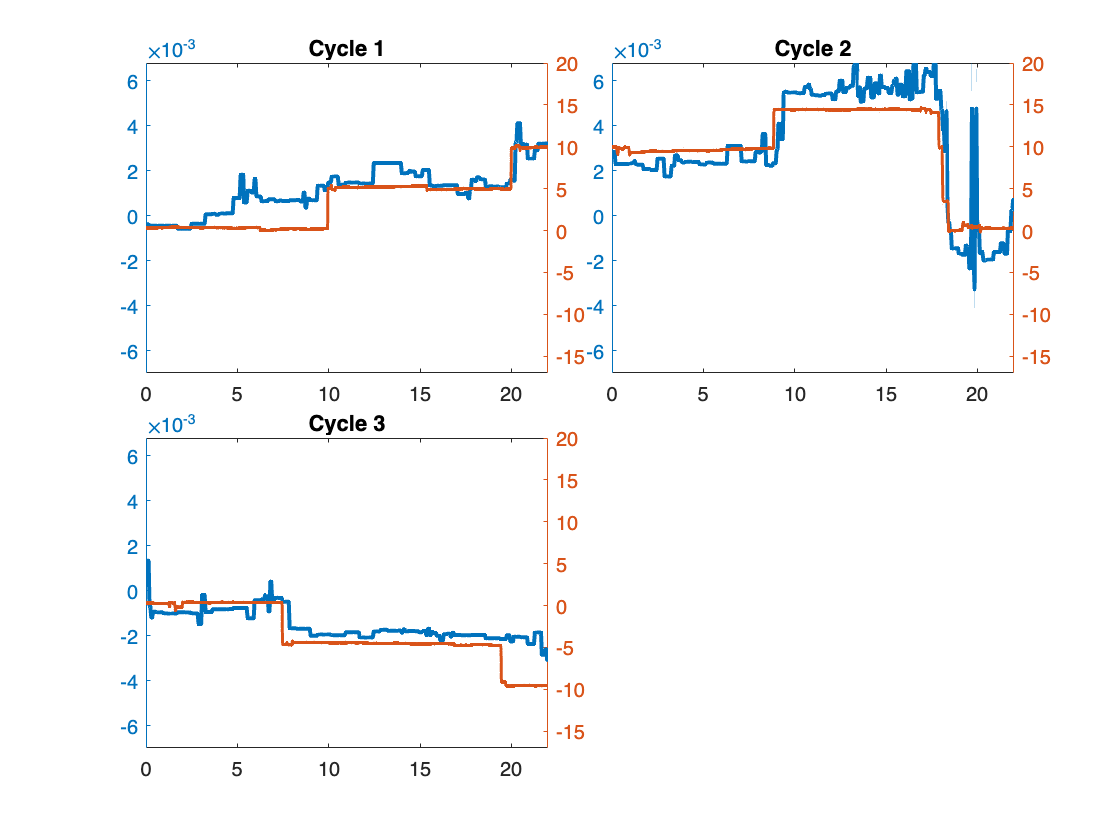

PERIOD_TIME  = 22;
WL_DEN_LVL = 6; 
WL_THR_MTD = 'Bayes'; 
WL_TYPE = 'bior1.5';
PEAK_PROM_CAP = .5e-3;
PEAK_PROM_COIL = 0.2;

START_TIME = 1;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;

corra = zeros(1,9);
clear outarr


locs = floor(START_TIME*sampling_rate+1):floor(PERIOD_TIME*sampling_rate):length(capDataLocal);
coilLocs = 1000*START_TIME+1:floor(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 10]) % Maximum allowed = 10 segments

    outarr{peaknum,1} = wlcomp(capDataPreproc(locs(peaknum):locs(peaknum+1)),WL_TYPE,WL_DEN_LVL,0);

    outarr{peaknum,2} = capDataPreproc(locs(peaknum):locs(peaknum+1));

end
clear capvar coilvar
coilvar = [];
capvar = [];
clf
tiledlayout(2,2,'TileSpacing','tight')
for ix = 1:3 % 3 * 22 > 66
    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000 + 1.2);

        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on


        ylim([-7e-3 6.8e-3])


        yyaxis right

        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on

        ylim([-17 20])
        hold off
        xlim([0 PERIOD_TIME])
        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1})); % RAW
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

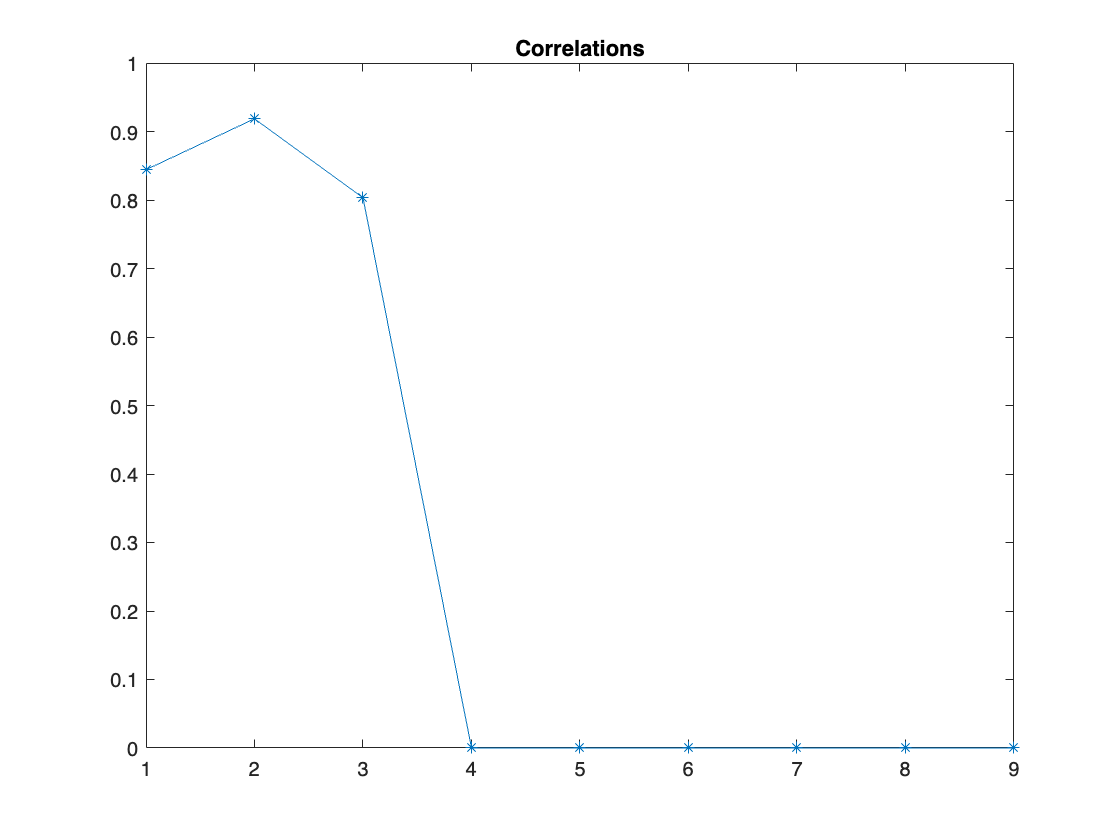


clf
plot(corra,"*-")
title("Correlations")

max(corra(corra ~= 0))

ans = 0.9186

mean(corra(corra ~= 0))

ans = 0.8553

std(corra(corra ~= 0))

ans = 0.0584

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

16.Horizontal Smooth 0.5 hz

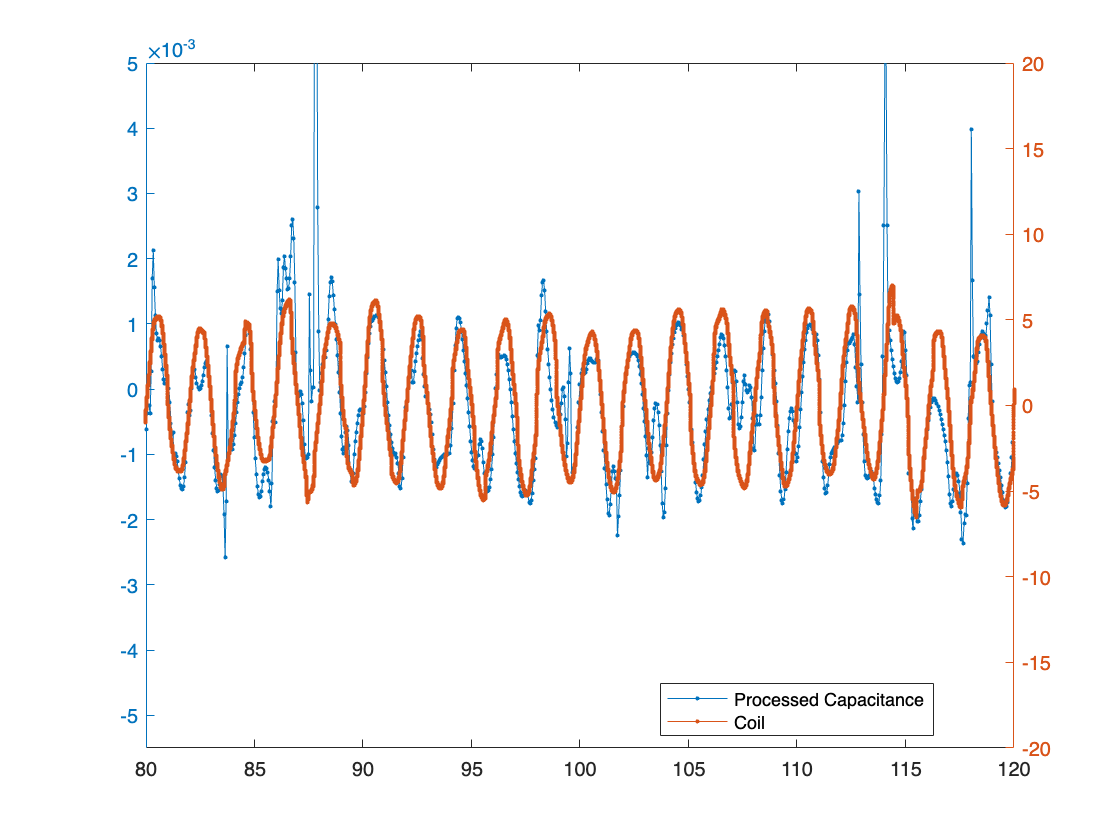

spr_adjustment = 20.85; % Need finer timing for shorter durations
clf
capDataMain = capDataSmoothPursuit0_t; % H column

capDataMain = filloutliers(capDataMain,'previous','movmedian',10);

mainCoil = smoothPursuit0_5;

coilTime = linspace(1,length(mainCoil),length(mainCoil))*0.001;
capTime = linspace(1,length(capDataMain),...
    length(capDataMain))/spr_adjustment;

%= Data Preprocessing
capDataPreproc = detrend(capDataMain,0);
capDataPreproc = circshift(capDataPreproc,-18);

capDataProcessed = wdes(capDataPreproc,3,'MiniMax','Bior3.3');
%=

yyaxis left
plot(capTime,capDataProcessed,'.-')
ylim([-5.5e-3 5e-3])
hold on
yyaxis right
plot(coilTime,mainCoil,'.-')
ylim([-20 20])
hold off
legend("Processed Capacitance","Coil",Location="best")
xlim([80 120])

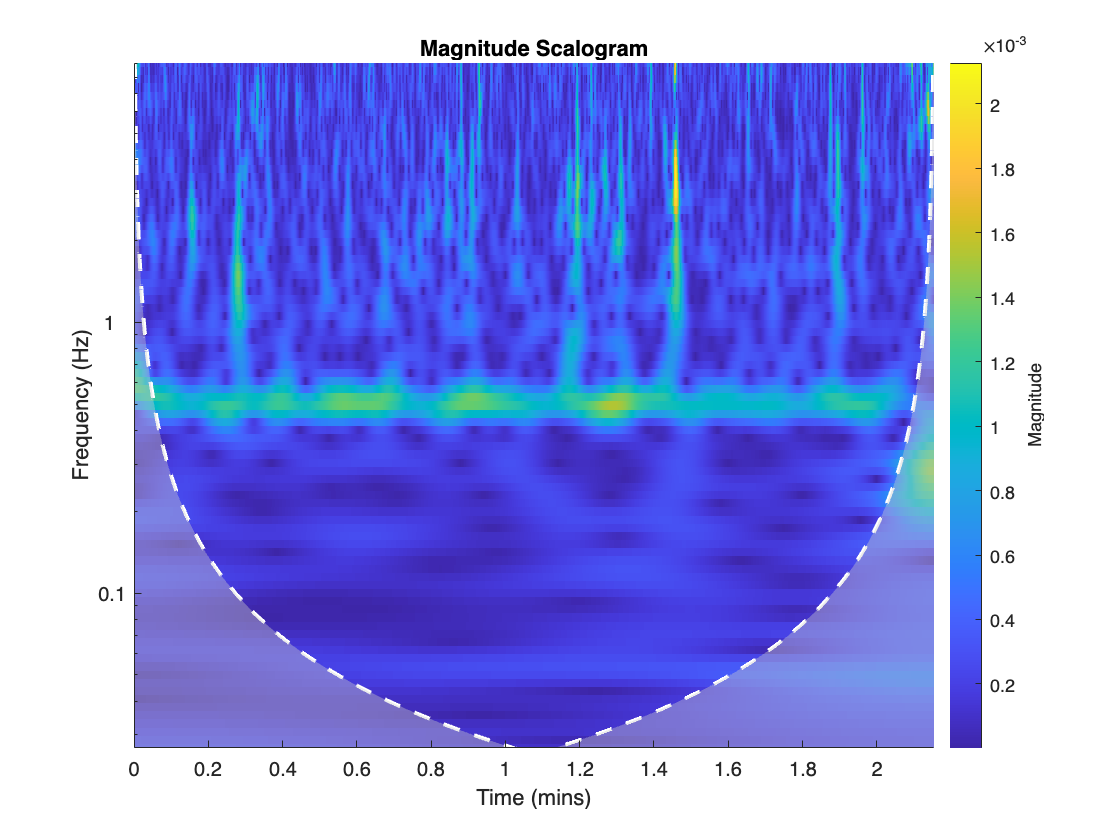

cwt(capDataPreproc,sampling_rate)

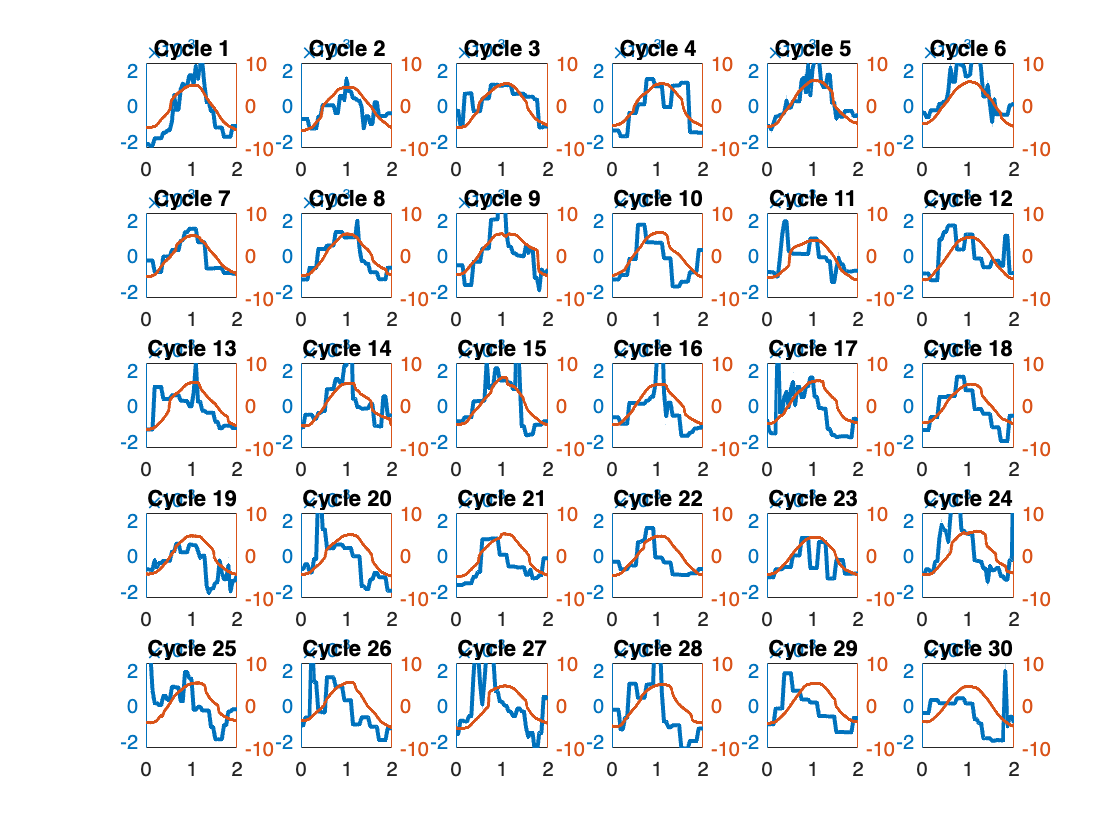

PERIOD_TIME  = 2;
WL_DEN_LVL = 2; 
WL_THR_MTD = 'Bayes';
WL_TYPE = 'bior1.5';
PEAK_PROM_CAP = .5e-3;
PEAK_PROM_COIL = 0.2;

START_TIME = 23.5;

capDataLocal = capDataPreproc;
coilDataLocal = mainCoil;
corra = zeros(1,30);

clear coilvar
clear capvar
coilvar = [];
capvar = [];

locs = floor(START_TIME*spr_adjustment+1):round(PERIOD_TIME*spr_adjustment):length(capDataLocal);
coilLocs = 1000*START_TIME+1:round(PERIOD_TIME*1000):length(coilDataLocal);
for peaknum = 1 : min([length(locs)-1 30]) 
    capuse = capDataPreproc(locs(peaknum):locs(peaknum+1));
    
    outarr{peaknum,1} = wdes(capuse,WL_DEN_LVL,WL_THR_MTD,WL_TYPE);

    outarr{peaknum,2} = capuse;

end
clf
tiledlayout(5,6,'TileSpacing','tight')
for ix = [1:30] % 30 * 2

    nexttile
    if ix <= length(outarr)

        yyaxis left
        tsCap = linspace(0,PERIOD_TIME,length(outarr{ix,1}));
        tsCoil = linspace(0,PERIOD_TIME,PERIOD_TIME*1000+1.2);
        plot(tsCap, outarr{ix,1},LineWidth=2);
        hold on
        ylim([-2.4e-3 2.4e-3])

        yyaxis right

        plot(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),LineWidth=1.5);
        hold on

        ylim([-10 10])
        hold off
        xlim([0 2])

        dsCoil = interp1(tsCoil,coilDataLocal(coilLocs(ix):coilLocs(ix+1)),tsCap);
        coilvar = [coilvar;dsCoil'];
        capvar = [capvar;outarr{ix,1}];
        mincorr = min(corrcoef(dsCoil,outarr{ix,1}));
        corra(1,ix) = mincorr(1);
    end
    title("Cycle " + ix);
end

max(corra(corra ~= 0))

ans = 0.9213

mean(corra(corra ~= 0))

ans = 0.5645

std(corra(corra ~= 0))

ans = 0.2440

[xData, yData] = prepareCurveData( coilvar, capvar );
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
[fitresult, gof] = fit( xData, yData, ft, opts );

Denoise Function Implementations

function wden_out = wdes(signal_in,lvls,rules,wls)
    wden_out = wdenoise(signal_in,lvls,...
        'DenoisingMethod',rules,...
        'Wavelet',wls,...
        'NoiseEstimate','LevelIndependent');
end

function wl_out = wlcomp(signal_in,wltype,lvl,thr_in)
    [thr,sorh,keepapp] = ddencmp('den','wv',signal_in);
    if thr_in ~= 0
        thr = thr_in;
    end
    wl_out = wdencmp('gbl',signal_in,wltype,lvl,thr,sorh,keepapp);
end